# DSZOB, cvičenie 5.

## **Zadanie:**

## **Úloha 1 Windowing**

Vygenerujte signál pre časový úsek 0-1s:

- Zložený signál obsahujúci 5 rôznych frekvencií a so vzorkovacou frekvenciou 44.1kHz. (vznikne aditívne so zvolenými násobnými koeficientami)

Vypočítajte Fourierovo spektrum (funkcia fft) zo selektovaného kratšieho časového úseku tohto signálu nasledujúcimi spôsobmi:

- Hammingovo okienko (windowing)

- Pravouhlé okienko (windowing)

Aký bol rozdiel vo výslednej Fourierovej transformácii pri použití Hammingovho a Pravouhlého okienka?

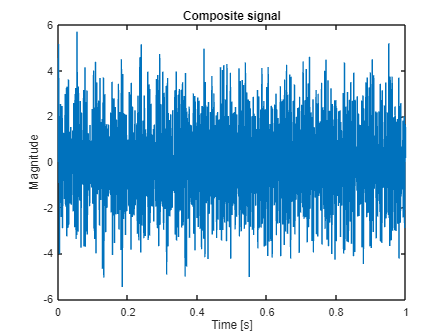

% Riesenie / Solution
fs = 44100;
time_axis = 0:1/fs:1;

composite = sin(time_axis * rand() * 600 * 2 * pi);
for j = 1:5 
    composite = composite + sin(time_axis * rand() * 600 * 2 * pi);
end
plot(time_axis, composite);
xlabel("Time [s]");
ylabel("Magnitude");
title("Composite signal");

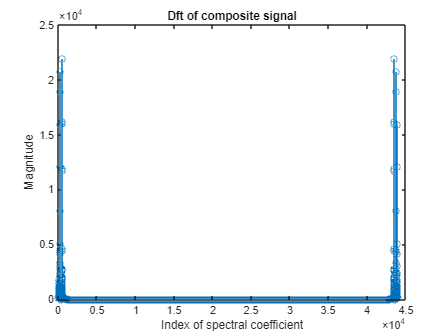

composite_dft = fft(composite);
stem(abs(composite_dft));
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
title("Dft of composite signal");

composite_rect = composite(1,1:1024) .* [zeros(1,300), ones(1, 424), zeros(1, 300)];
composite_hamming = composite(1,1:1024) .* hamming(1024).'; % Non transposed hamming tried to hurt my laptop

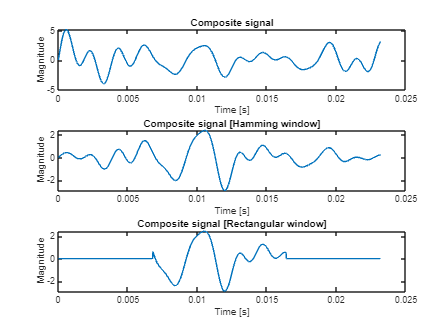

subplot(3,1,1);
plot(time_axis(1,1:1024), composite(1,1:1024));
xlabel("Time [s]");
ylabel("Magnitude");
title("Composite signal");

subplot(3,1,2);
plot(time_axis(1,1:1024), composite_hamming);
xlabel("Time [s]");
ylabel("Magnitude");
title("Composite signal [Hamming window]");

subplot(3,1,3);
plot(time_axis(1,1:1024), composite_rect);
xlabel("Time [s]");
ylabel("Magnitude");
title("Composite signal [Rectangular window]");

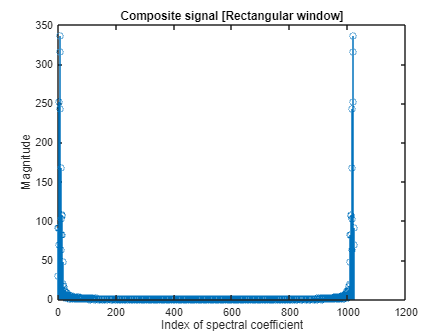

close all;
stem(abs(fft(composite_rect)));
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
title("Composite signal [Rectangular window]");

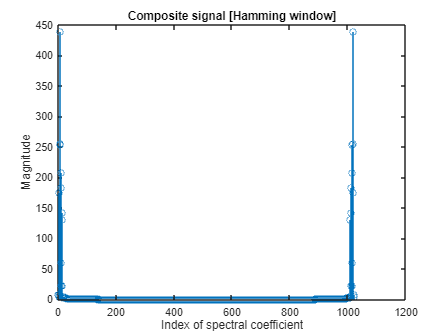

stem(abs(fft(composite_hamming)));
xlabel("Index of spectral coefficient");
ylabel("Magnitude");
title("Composite signal [Hamming window]");

## **Úloha 2 **Redukcia dát v spektrálnej oblasti 

- Načítajte zvukovú stopu (napr. hudbu z dokumentového serveru) ako signál.

- Vizualizujte signál (celý aj detail okienka použitého v bode 3).

- Spočítajte kosínovú transformáciu (*dct*) aspoň pre jedno okienko a vizualizujte spektrum okienka (použite funkciu matlabu *stem*).

- Za pomoci cyklu *for* prejdite celým signálom tak, že vyberiete okienka bez prekryvu.

- Pre jednotlivé okienka vypočítajte *dct*, nastavte amplitúdy spektrálnych koeficientov, ktoré sú menšie ako zvolený prah (teda všetko, čo má menšiu amplitúdu ako zvolený prah) na hodnotu 0 a vypočítajte spätnú kosínovú transformáciu (*idct*). Takto získate nový, filtrovaný signál.

- Vizualizujte spektrum signálu pred a po filtrácií formou spektrogramu.

Vypočujte si výstupný, filtrovaný signál s rôznymi prahmi nulovania spektrálnych koeficientov. Porovnajte. Pri akej hodnote prahu došlo k značnému znehodnoteniu kvality zvukovej stopy?

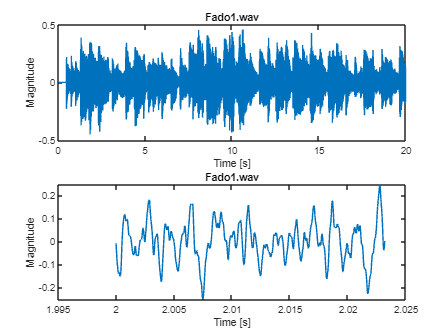

% Riesenie / Solution
fado = audioread("Asignments\Assignment_3\fado1.wav");
fado_info = audioinfo("Asignments\Assignment_3\fado1.wav");
fs = fado_info.SampleRate;
time_axis = 0:1/fs:fado_info.Duration;
time_axis(end) = [];    % Fix for rounding issue

fado_sample = fado(fs*2:fs*2+1024); % 1024 samples starting from second 2 

subplot(2,1,1);
plot(time_axis, fado);
title("Fado1.wav");
xlabel("Time [s]");
ylabel("Magnitude");
subplot(2,1,2);
plot(time_axis(fs*2:fs*2+1024), fado_sample);
title("Fado1.wav");
xlabel("Time [s]");
ylabel("Magnitude");

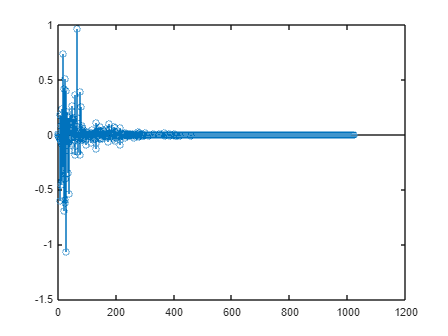

close all;
stem(dct(fado_sample));